clear, clc
datadir = '/media/dell/zhou/A_arousal_analysis/data';
load("/media/dell/zhou/A_arousal_analysis/scripts/A_temp_dat.mat")

## study6 pattern

load(fullfile(datadir, "A_MDD_pls_decoder_study6.mat"), 'bpls');
FC_study7_combat = combat_ref([FC_study6; FC_study7]', ...
    [ones(67, 1); 2*ones(46, 1)], ...
    [[age_study6, sex_study6];[age_study7, sex_study7]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


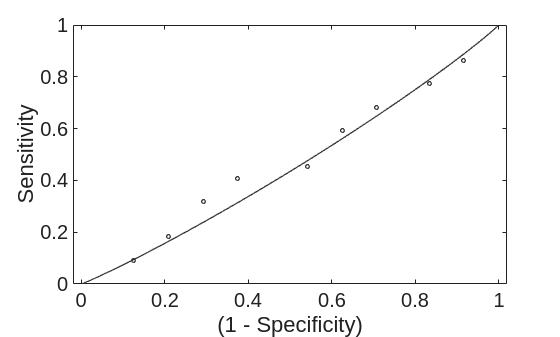

FC_study7_combat = FC_study7_combat(:, 68:end)';
pred_label = [ones(numel(label_study7), 1) FC_study7_combat] * bpls;
clear FC_study7_combat
figure;
roc = roc_plot(pred_label, label_study7>0, 'nooutput'); 

fprintf('\n Study 6 signature predicts study 7: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 signature predicts study 7: ACC = 54.35% ± 7.344%, P = 0.8846, AUC = 0.4924, d = -0.1653 


FC_study8_combat = combat_ref([FC_study6; FC_study8]', ...
    [ones(67, 1); 2*ones(101, 1)], ...
    [[age_study6, sex_study6];[age_study8, sex_study8]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


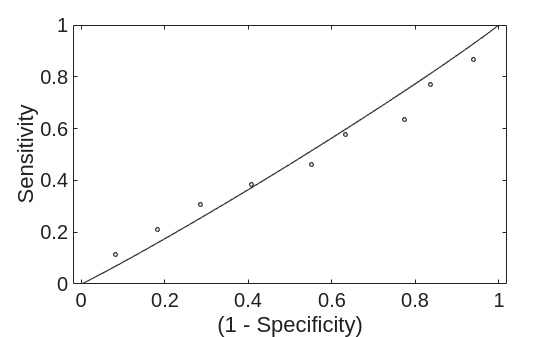

FC_study8_combat = FC_study8_combat(:, 68:end)';
pred_label = [ones(numel(label_study8), 1) FC_study8_combat] * bpls;
clear FC_study8_combat
figure;
roc = roc_plot(pred_label, label_study8>0, 'nooutput'); 

fprintf('\n Study 6 signature predicts study 8: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 signature predicts study 8: ACC = 54.46% ± 4.955%, P = 0.6194, AUC = 0.4761, d = -0.0935 


FC_study9_combat = combat_ref([FC_study6; FC_study9]', ...
    [ones(67, 1); 2*ones(126, 1)], ...
    [[age_study6, sex_study6];[age_study9, sex_study9]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


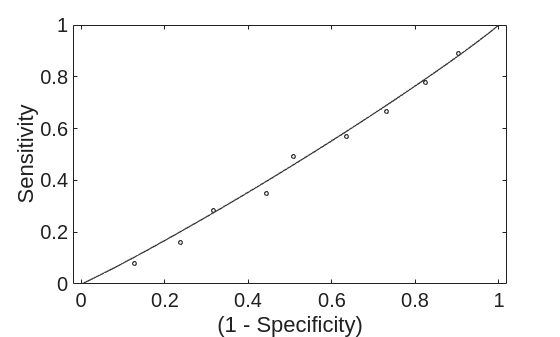

FC_study9_combat = FC_study9_combat(:, 68:end)';
pred_label = [ones(numel(label_study9), 1) FC_study9_combat] * bpls;
clear FC_study9_combat
figure;
roc = roc_plot(pred_label, label_study9>0, 'nooutput'); 

fprintf('\n Study 6 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 signature predicts study 9: ACC = 51.59% ± 4.452%, P = 0.7894, AUC = 0.4657, d = -0.1202 


## study 7 pattern

load(fullfile(datadir, "A_MDD_pls_decoder_study7.mat"), 'bpls');
FC_study6_combat = combat_ref([FC_study7; FC_study6]', ...
    [ones(46, 1); 2*ones(67, 1)], ...
    [[age_study7, sex_study7];[age_study6, sex_study6]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


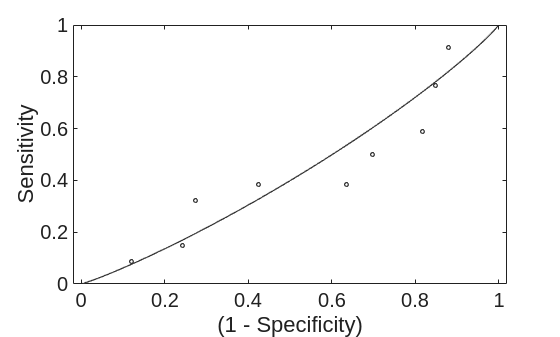

FC_study6_combat = FC_study6_combat(:, 47:end)';
pred_label = [ones(numel(label_study6), 1) FC_study6_combat] * bpls;
clear FC_study6_combat
figure;
roc = roc_plot(pred_label, label_study6>0, 'nooutput');

fprintf('\n Study 7 signature predicts study 6: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 6: ACC = 53.73% ± 6.091%, P = 0.7147, AUC = 0.4296, d = -0.2567 


FC_study8_combat = combat_ref([FC_study7; FC_study8]', ...
    [ones(46, 1); 2*ones(101, 1)], ...
    [[age_study7, sex_study7];[age_study8, sex_study8]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


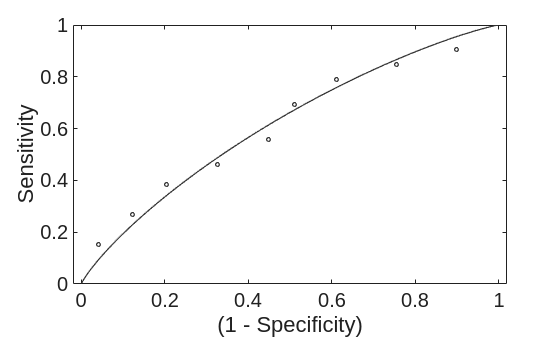

FC_study8_combat = FC_study8_combat(:, 47:end)';
pred_label = [ones(numel(label_study8), 1) FC_study8_combat] * bpls;
clear FC_study8_combat
figure;
roc = roc_plot(pred_label, label_study8>0, 'nooutput'); 

fprintf('\n Study 7 signature predicts study 8: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 8: ACC = 63.37% ± 4.794%, P = 0.02133, AUC = 0.6295, d = 0.4193 


FC_study9_combat = combat_ref([FC_study7; FC_study9]', ...
    [ones(46, 1); 2*ones(126, 1)], ...
    [[age_study7, sex_study7];[age_study9, sex_study9]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


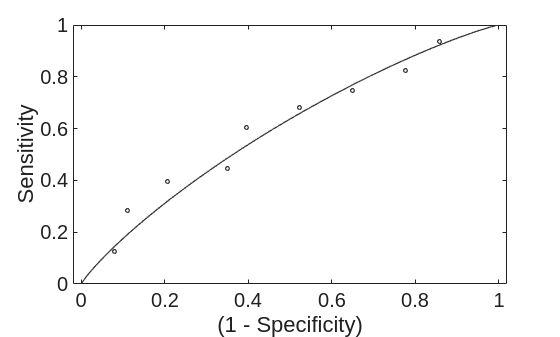

FC_study9_combat = FC_study9_combat(:, 47:end)';
pred_label = [ones(numel(label_study9), 1) FC_study9_combat] * bpls;
clear FC_study9_combat
figure;
roc = roc_plot(pred_label, label_study9>0, 'nooutput');

fprintf('\n Study 7 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 9: ACC = 60.32% ± 4.358%, P = 0.02554, AUC = 0.6145, d = 0.3503 


## study 8 pattern

load(fullfile(datadir, "A_MDD_pls_decoder_study8.mat"), 'bpls');
FC_study6_combat = combat_ref([FC_study8; FC_study6]', ...
    [ones(101, 1); 2*ones(67, 1)], ...
    [[age_study8, sex_study8];[age_study6, sex_study6]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


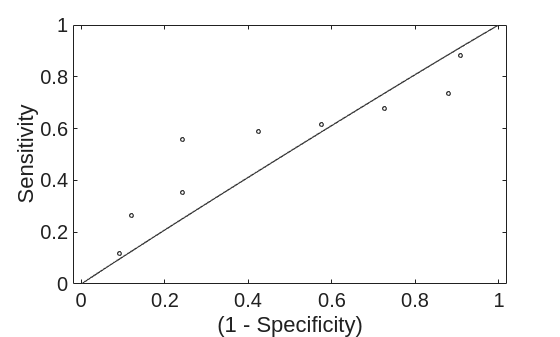

FC_study6_combat = FC_study6_combat(:, 102:end)';
pred_label = [ones(numel(label_study6), 1) FC_study6_combat] * bpls;
clear FC_study6_combat
figure;
roc = roc_plot(pred_label, label_study6>0, 'nooutput');

fprintf('\n Study 8 signature predicts study 6: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 signature predicts study 6: ACC = 65.67% ± 5.801%, P = 0.01942, AUC = 0.5584, d = 0.03062 


FC_study7_combat = combat_ref([FC_study8; FC_study7]', ...
    [ones(101, 1); 2*ones(46, 1)], ...
    [[age_study8, sex_study8];[age_study7, sex_study7]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


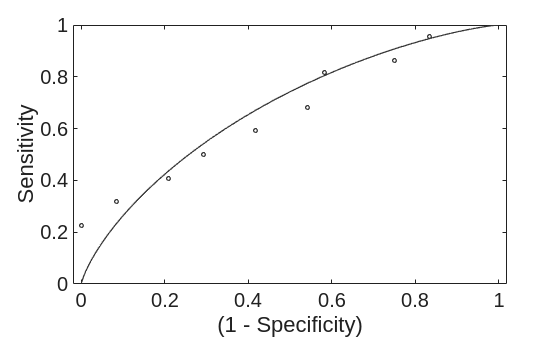

FC_study7_combat = FC_study7_combat(:, 102:end)';
pred_label = [ones(numel(label_study7), 1) FC_study7_combat] * bpls;
clear FC_study7_combat
figure;
roc = roc_plot(pred_label, label_study7>0, 'nooutput');

fprintf('\n Study 8 signature predicts study 7: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 signature predicts study 7: ACC = 65.22% ± 7.022%, P = 0.1027, AUC = 0.6742, d = 0.6504 


FC_study9_combat = combat_ref([FC_study8; FC_study9]', ...
    [ones(101, 1); 2*ones(126, 1)], ...
    [[age_study8, sex_study8];[age_study9, sex_study9]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


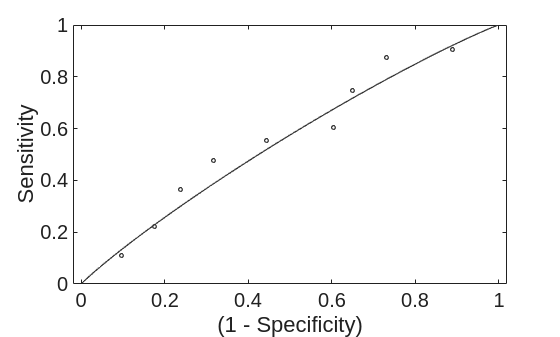

FC_study9_combat = FC_study9_combat(:, 102:end)';
pred_label = [ones(numel(label_study9), 1) FC_study9_combat] * bpls;
clear FC_study9_combat
figure;
roc = roc_plot(pred_label, label_study9>0, 'nooutput');

fprintf('\n Study 8 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 signature predicts study 9: ACC = 59.52% ± 4.373%, P = 0.04004, AUC = 0.5756, d = 0.1901 


## study 9 pattern

load(fullfile(datadir, "A_MDD_pls_decoder_study9.mat"), 'bpls');
FC_study6_combat = combat_ref([FC_study9; FC_study6]', ...
    [ones(126, 1); 2*ones(67, 1)], ...
    [[age_study9, sex_study9];[age_study6, sex_study6]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


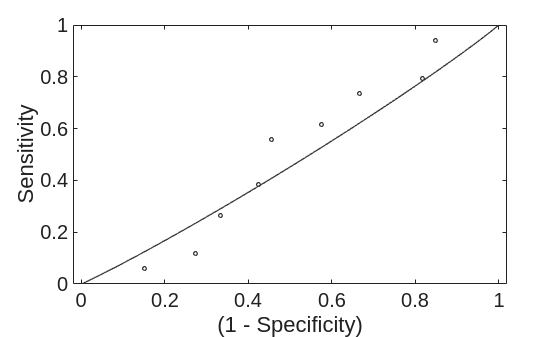

FC_study6_combat = FC_study6_combat(:, 127:end)';
pred_label = [ones(numel(label_study6), 1) FC_study6_combat] * bpls;
clear FC_study6_combat
figure;
roc = roc_plot(pred_label, label_study6>0, 'nooutput');

fprintf('\n Study 9 signature predicts study 6: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 signature predicts study 6: ACC = 56.72% ± 6.053%, P = 0.3927, AUC = 0.5062, d = -0.1216 


FC_study7_combat = combat_ref([FC_study9; FC_study7]', ...
    [ones(126, 1); 2*ones(46, 1)], ...
    [[age_study9, sex_study9];[age_study7, sex_study7]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


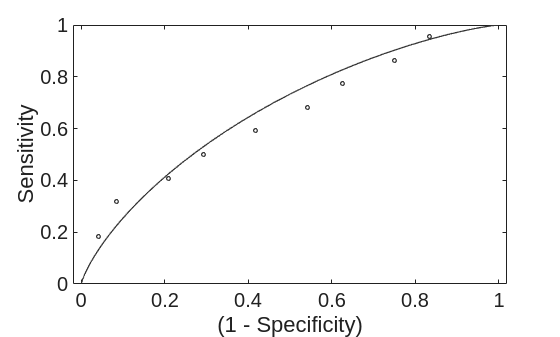

FC_study7_combat = FC_study7_combat(:, 127:end)';
pred_label = [ones(numel(label_study7), 1) FC_study7_combat] * bpls;
clear FC_study7_combat
figure;
roc = roc_plot(pred_label, label_study7>0, 'nooutput');

fprintf('\n Study 9 signature predicts study 7: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 signature predicts study 7: ACC = 65.22% ± 7.022%, P = 0.1027, AUC = 0.6648, d = 0.6222 


FC_study8_combat = combat_ref([FC_study9; FC_study8]', ...
    [ones(126, 1); 2*ones(101, 1)], ...
    [[age_study9, sex_study9];[age_study8, sex_study8]], ...
    1, 'ref', 1);

[combat] Harmonizing to reference batch 1
[combat] Found 2 batches
[combat] Adjusting for 2 covariate(s) of covariate level(s)
[combat] Standardizing Data across features
[combat] Fitting L/S model and finding priors
[combat] Finding parametric adjustments
[combat] Adjusting the Data


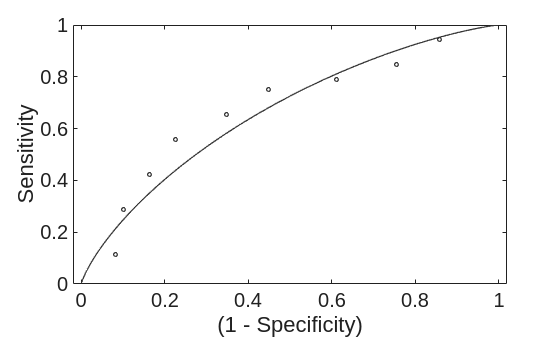

FC_study8_combat = FC_study8_combat(:, 127:end)';
pred_label = [ones(numel(label_study8), 1) FC_study8_combat] * bpls;
clear FC_study8_combat
figure;
roc = roc_plot(pred_label, label_study8>0, 'nooutput');

fprintf('\n Study 9 signature predicts study 8: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 signature predicts study 8: ACC = 68.32% ± 4.629%, P = 0.0008905, AUC = 0.6907, d = 0.5991 
